% Import data
data_HW3 = readtable("Top 100 Genes.xlsx","ReadRowNames",true);

% Inspect table
head(data_HW3,5)

ans = 5×102 table
                  SurvivalDays    Test     LIX1L        NEU4       TTC12      IFITM10       EIF3L       DGCR14       MRPS27       KHDRBS3      CCDC89       PHB2       TTLL1      PPAPDC1A     TNNC2        WWP2      C2orf27A      USE1       FCHSD2      EEF1G      C20orf196    RPL19P12     LYSMD1       OLIG1       ZNF780A       LUZP2       MYO15A       RPL3       PCBP3      C7orf53      TSSC1       PKNOX2        GAS5    

% Create new train and test sets for X and Y using 0s (train) and 1s (test)
% in Test column

Xtrain = data_HW3{data_HW3.Test==0,3:end};
Xtest = data_HW3{data_HW3.Test==1,3:end};

Ytrain = data_HW3{data_HW3.Test==0,1};
Ytest = data_HW3{data_HW3.Test==1,1};


## Multi-linear Regression using Hold-out Validation

### Normal Regression

% Find correlation of all 100 genes and then extract data for top 15 genes
r_100 = corr(Xtrain,Ytrain);

r_100 =     0.5149
    0.5600
   -0.5379
    0.5254
    0.5730
    0.5421
    0.5538
    0.4513
   -0.5338
    0.5141


[r_15,index_15] = maxk(abs(r_100),15);

r_15 =     0.6297
    0.5973
    0.5731
    0.5730
    0.5701
    0.5687
    0.5656
    0.5647
    0.5639
    0.5600


index_15 =     34
    43
    51
     5
    20
    40
    29
    73
    57
     2



% Create new training and test sets with top 15 genes 

index_15 =      2
     5
     6
     7
    17
    20
    29
    34
    40
    43


Xtrain_15 = Xtrain(:,index_15);
Xtest_15 = Xtest(:,index_15);

ans = 0.6297


mdl = fitlm(Xtrain_15,Ytrain)

mdl = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7 + x8 + x9 + x10 + x11 + x12 + x13 + x14 + x15

Estimated Coefficients:
                   Estimate      SE        tStat        pValue  
                   ________    ______    _________    __________

    (Intercept)     627.65     54.797       11.454    2.7843e-12
    x1              141.14       51.1        2.762     0.0098648
    x2               -4.73      140.2    -0.033738       0.97332
    x3              48.972     119.86      0.40858       0.68585
    x4              177.62     122.02       1.4556       0.15623
    x5             -257.19     123.27      -2.0864      0.045844
    x6              252.87     152.73       1.6557       0.10857
    

% Calculate r, r^2, RMSE and average error
Ypred_norm = predict(mdl,Xtest_15);
r_norm = corr(Ytest,Ypred_norm)

r_norm = 0.0816

r2_norm = r_norm^2

r2_norm = 0.0067

RMSE = sqrt(mean((Ypred_norm-Ytest).^2))   

RMSE = 359.6592

avg_error = mean(abs(Ypred_norm-Ytest))

avg_error = 296.3538

### Repeat with Lasso Regression

[B1, Fit] = lasso(Xtrain_15,Ytrain,'CV',10);
B1_coeff = B1(:,Fit.Index1SE)

B1_coeff =    27.5354
         0
   35.0768
   14.9643
         0
   22.3043
         0
  143.3208
    3.9919
         0


B1_intercept = Fit.Intercept(Fit.Index1SE)

B1_intercept = 598.1095

Ypred_lasso = Xtest_15 * B1_coeff + B1_intercept;

r_lasso = corr(Ypred_lasso,Ytest)

r_lasso = 0.1037

r2_lasso =  r_lasso^2

r2_lasso = 0.0107

RMSE_lasso = sqrt(mean((Ypred_lasso-Ytest).^2))   

RMSE_lasso = 310.4699

avg_error_lasso = mean(abs(Ypred_lasso-Ytest))

avg_error_lasso = 255.1037

### Repeat with Stepwise Regression

[B2,~,~,~,stats] = stepwisefit(Xtrain_15,Ytrain);

Initial columns included: none
Step 1, added column 8, p=3.57549e-06
Step 2, added column 1, p=0.000962066
Step 3, added column 3, p=0.0485883
Final columns included:  1 3 8 
    'Coeff'       'Std.Err.'    'Status'    'P'         
    [ 65.2065]    [ 31.8982]    'In'        [    0.0474]
    [ 52.2210]    [ 64.1681]    'Out'       [    0.4206]
    [149.7515]    [ 73.6695]    'In'        [    0.0486]
    [131.6148]    [ 87.8463]    'Out'       [    0.1419]
    [-38.5347]    [ 82.3811]    'Out'       [    0.6425]
    [ 43.3180]    [ 90.0316]    'Out'       [    0.6330]
    [ 29.5171]    [ 95.3956]    'Out'       [    0.7586]
    [393.7172]    [ 90.9898]    'In'        [9.4619e-05]
    [ 42.2050]    [ 67.8657]    'Out'       [    0.5375]
    [ -0.3560]    [ 99.5721]    'Out'       [    0.9972]
    [ 64.4157]    [ 69.1039]    'Out'       [    0.3568]
    [100.5944]    [ 53.7852]    'Out'       [    0.0688]
    [ 88.5513]    [ 70.0971]    'Out'       [    0.2138]
    [  5.7396]    [ 88.2548

Ypred_step = Xtest_15(:,[1,10,15])*B2([1,10,15]) + stats.intercept;
r_stepwise = corr(Ypred_step,Ytest)

r_stepwise = 0.1894

r2_stepwise =  r_stepwise^2

r2_stepwise = 0.0359

RMSE_stepwise = sqrt(mean((Ypred_step-Ytest).^2))   

RMSE_stepwise = 347.2721

avg_error_stepwise = mean(abs(Ypred_step-Ytest))

avg_error_stepwise = 281.9262

## Compare Correlation of 3 Methods w/ Bar Graph

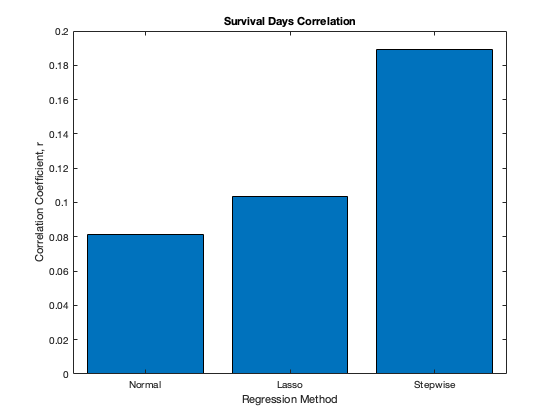

% Create labels for bar graphs
x = categorical({'Normal','Lasso','Stepwise'});
x = reordercats(x,{'Normal','Lasso','Stepwise'});

% Correlation bar graph
bar(x,[r_norm,r_lasso,r_stepwise])
xlabel("Regression Method")
ylabel("Correlation Coefficient, r")
title("Survival Days Correlation")